## 2. Series de Fourier

### **2.1 Conceptos teóricos previos sobre funciones trigonométricas**

Representación de la función f(x) = sin(x)

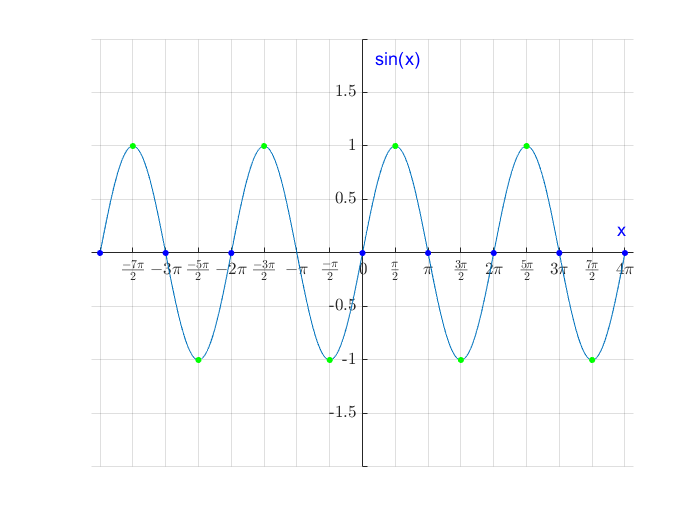

clf
t = linspace(-4*pi,4*pi,10000);
seno = sin(t); xCeros = [-4*pi -3*pi -2*pi pi 0 pi 2*pi 3*pi 4*pi];
yCeros = repmat(0,1,9);
xExtremos = [-7*pi/2 -5*pi/2 -3*pi/2 -pi/2 pi/2 3*pi/2 5*pi/2 7*pi/2];
yExtremos = [1 -1 1 -1 1 -1 1 -1];
createfigure(t,seno,xCeros,yCeros,xExtremos,yExtremos)
ylim([-2,2])
xlim([-13,13])

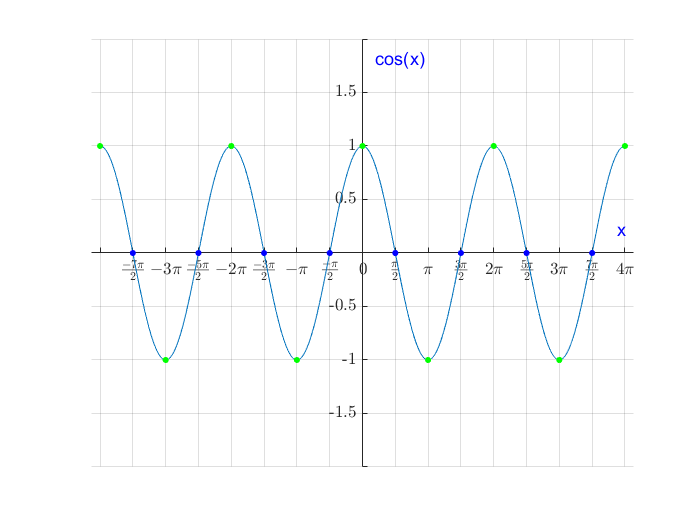

coseno = cos(t);
%sierra = t / pi;
xExtremos = [-4*pi -3*pi -2*pi -pi 0 pi 2*pi 3*pi 4*pi];
yCeros = repmat(0,1,8);
xCeros = [-7*pi/2 -5*pi/2 -3*pi/2 -pi/2 pi/2 3*pi/2 5*pi/2 7*pi/2];
yExtremos = [1 -1 1 -1 1 -1 1 -1 1];
createfigure(t,coseno,xCeros,yCeros,xExtremos,yExtremos)
ylim([-2,2])
xlim([-13,13])
ylabel('cos(x)')

### 2.3 Ejemplo de construcción de una serie de Fourier

Ejemplo de Series de Fourier para la función onda de Sierra, considerando para el orden N =  2^j para j = 0,1,2,3,4...

t = linspace(0.1,0.99,100);
f = t - floor(t);
Sf1 = serieFourier(t,1);
Sf2 = serieFourier(t,2);
Sf4 = serieFourier(t,4);
Sf8 = serieFourier(t,8);
Sf16 = serieFourier(t,16);
Sf32 = serieFourier(t,32);
Sf64 = serieFourier(t,64);
Sf128 = serieFourier(t,128);
Sf256 = serieFourier(t,256);
Sf512 = serieFourier(t,512);
Sf1024 = serieFourier(t,1024);
Sf2048 = serieFourier(t,2048);
Sf4096 = serieFourier(t,4096);

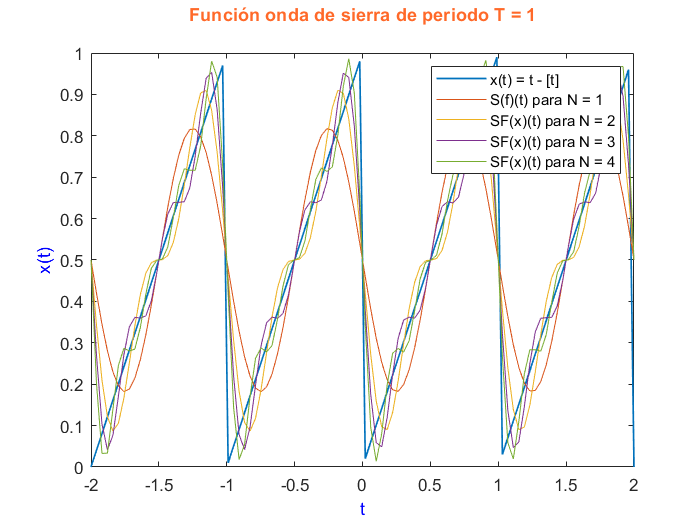

x = linspace(-2,2,100);
f2 = x - floor(x);
Sef1 = serieFourier(x,1);
Sef2 = serieFourier(x,2);
Sef4 = serieFourier(x,4);
Sef3 = serieFourier(x,3);
clf;
ondaSierra(x,f2)
hold on;
plot(x,Sef1);
plot(x,Sef2);
plot(x,Sef3);
plot(x,Sef4);
%plot(t,Sf5);
legend('x(t) = t - [t]', 'S(f)(t) para N = 1','SF(x)(t) para N = 2', 'SF(x)(t) para N = 3', 'SF(x)(t) para N = 4');
hold off;

Cálculo de los errores para las series de Fourier de ordenes N = 1,2,3...,10

f = f'

f =     0.1000
    0.1090
    0.1180
    0.1270
    0.1360
    0.1449
    0.1539
    0.1629
    0.1719
    0.1809


Sf1 = Sf1'

Sf1 =     0.3129
    0.2987
    0.2851
    0.2722
    0.2600
    0.2485
    0.2379
    0.2281
    0.2192
    0.2112


## **Errores en  **$L^{\infty }$**y **$L^1$

**Errores en  **$L^{\infty }$

Error máximo de los errores en los puntos del conjunto t : $E^{\infty }$

e1 = error(f,Sf1)

e1 = 0.4700

e2 = error(f,Sf2)

e2 = 0.4501

e4 = error(f,Sf4)

e4 = 0.4104

e8 = error(f,Sf8)

e8 = 0.3327

e16 = error(f,Sf16)

e16 = 0.1891

e32 = error(f,Sf32)

e32 = 0.0667

e64 = error(f,Sf64)

e64 = 0.0564

e128 = error(f,Sf128)

e128 = 0.0187

e256 = error(f,Sf256)

e256 = 0.0185

e512 = error(f,Sf512)

e512 = 0.0072

e1024 = error(f,Sf1024)

e1024 = 0.0025

e2048 = error(f,Sf2048)

e2048 = 0.0025

e4096 = error(f,Sf4096)

e4096 = 0.0012

eLinf = [e1 e2 e4 e8 e16 e32 e64 e128 e256 e512 e1024 e2048 e4096];

**Errores en  **$L^1$

h = t(2) - t(1);
eL1 = [errorL1(f,Sf1,h)];
eL1 = [eL1 errorL1(f,Sf2,h)];
eL1 = [eL1 errorL1(f,Sf4,h)];
eL1 = [eL1 errorL1(f,Sf8,h)];
eL1 = [eL1 errorL1(f,Sf16,h)];
eL1 = [eL1 errorL1(f,Sf32,h)];
eL1 = [eL1 errorL1(f,Sf64,h)];
eL1 = [eL1 errorL1(f,Sf128,h)];
eL1 = [eL1 errorL1(f,Sf256,h)];
eL1 = [eL1 errorL1(f,Sf512,h)];
eL1 = [eL1 errorL1(f,Sf1024,h)];
eL1 = [eL1 errorL1(f,Sf2048,h)];
eL1 = [eL1 errorL1(f,Sf4096,h)];

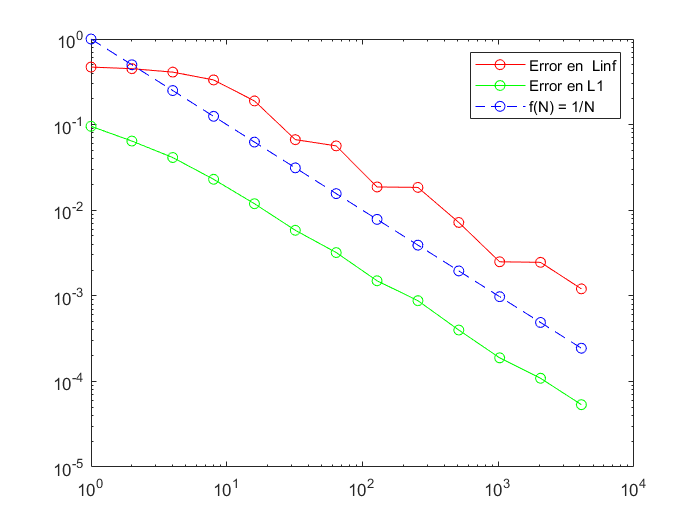

clf;
N = [1 2 4 8 16 32 64 128 256 512 1024 2048 4096];
loglog(N, eLinf,'-or', N, eL1, '-og',N,1./N, '--ob')
legend('Error en  Linf', 'Error en L1', 'f(N) = 1/N');

Nota: la enumeración de los apartados en los que está estructurado este código corresponde con los apartados y subapartados de la memoria del trabajo, en cuyo desarrollo se ha empleado este código.